t = 0:0.001:1;

x1 = zeros(length(t),1);
x2 = x1;

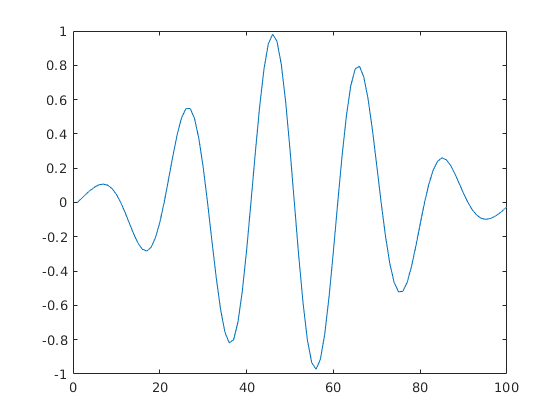

s = hamming(100)'.*sin(2*pi*50*t(1:100));

x1(100:100+length(s)-1) = s;
x2(300:300+length(s)-1) = s;

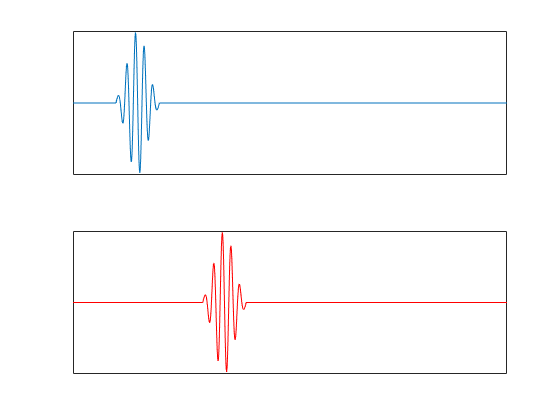

figure(); hold on; grid on; axis off;

subplot(2,1,1);
plot(t,x1);
set(gca,'xtick',[]); set(gca,'ytick',[]);
subplot(2,1,2)
plot(t,x2,'r');
set(gca,'xtick',[]); set(gca,'ytick',[]);
hold off;

[r,lags] = xcorr(x1,x2,'normalized');

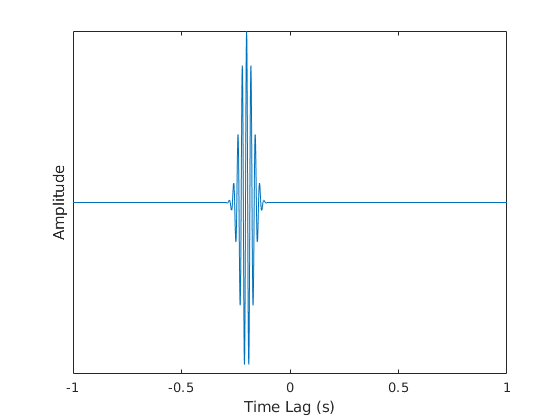

figure();
plot(lags*0.001,r);
set(gca,'ytick',[]);
ylabel('Amplitude');
xlabel('Time Lag (s)');